# Global Thresholding for everyone

## Load the data

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

% Transcriptomics data
data = readtable('Mod_data.xlsx')

data = 26269×49 table
      Ensembl_GeneID        BJ_Y1       BJ_Y2        BJ_Y3      BJ_OLD_1     BJ_OLD_2     BJ_OLD_3     IMR90_Y1    IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3    WI_38_Y1    WI_38_Y2     WI_38_Y3    WI_38_O1    WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD26_1

% Housekeeping genes with the ensembl ids
h_k_g = readtable('housekeeping_ens.csv');
% Human1 metabolic model.
model = readCbModel('Human-GEM_Cobra_v1.01.mat');

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.


## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes;
% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :);

## For loop to calculate the percentage of all the samples

% Initialise a table to store the results
results = table;
% Get expression data column names
expression_col = data_met.Properties.VariableNames(2:end);
results_colname = []


results_colname =

     []



results_percentage_hk = []


results_percentage_hk =

     []



now create the for loop 

% Iterate over each column of expression data
for i = 1:length(expression_col)
    % Select the expression data column
    col_name = expression_col{i};
    expfibroblast = data_met(:,1); 
    expfibroblast(:,2) = data_met(:, col_name); 
    expfibroblast.Properties.VariableNames{1} = 'gene';
    expfibroblast.Properties.VariableNames{2} = 'FPKMvalue';

    % Perform the calculations
    expfibroblast.logFPKMvalue = log10(expfibroblast{:,2} + 1); 
    expfibroblast.value = expfibroblast.logFPKMvalue - min(expfibroblast.logFPKMvalue); 

    % Calculate the threshold, creating a slider form 70 to 100
    percentage =90;
    up_threshold_fib = prctile(expfibroblast.value, percentage);

    % Filtering the data
    idx = expfibroblast.value >= up_threshold_fib;
    filtered_data = expfibroblast(idx, :);

    % Select the ensembl id of the core genes
    genes_table = data_met.Ensembl_GeneID;
    
    %% housekeeping
    % See how many housekeeping genes in the list have metabolic functions. 
    index_names = ismember(genes_table, h_k_g.converted_alias);
    hkg_met = data_met(index_names, :);

    % Now just the ensmbl id
    hkg_met_ens = hkg_met(:, "Ensembl_GeneID");

    % Finding the housekeeping genes among the filtered genes
    ens_filt_dat = filtered_data.gene;
    matching_names_idx = ismember(ens_filt_dat, hkg_met_ens.Ensembl_GeneID);
    matching_names = filtered_data(matching_names_idx, 1);

    % Calculate the percentage of maintenance genes
    percentage_hk = (length(matching_names.gene) / length(ens_filt_dat)) * 100;

    % Save the results in the table
    results{i, 'Column'} = {col_name};
    results{i, 'PorcentageHK'} = percentage_hk;
end

results_FPKM = results

results_FPKM = 48×2 table
       Column       PorcentageHK
    ____________    ____________

    {'BJ_Y1'   }       57.756   
    {'BJ_Y2'   }       57.756   
    {'BJ_Y3'   }       57.426   
    {'BJ_OLD_1'}       59.076   
    {'BJ_OLD_2'}       58.746   
    {'BJ_OLD_3'}       58.086   
    {'IMR90_Y1'}       60.726   
    {'IMR90_Y2'}       60.726   
    {'IMR90_Y3'}       60.396   
    {'IMR90_O1'}       60.396   
    {'IMR90_O2'}       58.746   
    {'IMR90_O3'}       61.056   
    {'WI_38_Y1'}       63.036   
    {'WI_38_Y2'}       62.376   
    {'WI_38_Y3'}       63.036   
    {'WI_38_O1'}       60.726   


% Show results
disp(results_FPKM);

         Column         PorcentageHK
    ________________    ____________

    {'BJ_Y1'       }       57.756   
    {'BJ_Y2'       }       57.756   
    {'BJ_Y3'       }       57.426   
    {'BJ_OLD_1'    }       59.076   
    {'BJ_OLD_2'    }       58.746   
    {'BJ_OLD_3'    }       58.086   
    {'IMR90_Y1'    }       60.726   
    {'IMR90_Y2'    }       60.726   
    {'IMR90_Y3'    }       60.396   
    {'IMR90_O1'    }       60.396   
    {'IMR90_O2'    }       58.746   
    {'IMR90_O3'    }       61.056   
    {'WI_38_Y1'    }       63.036   
    {'WI_38_Y2'    }       62.376   
    {'WI_38_Y3'    }       63.036   
    {'WI_38_O1'    }       60.726   
    {'WI_38_O2'    }       61.386   
    {'WI_38_O3'    }       60.726   
    {'HFF_PD16_1'  }       60.726   
    {'HFF_PD16_2'  }       60.396   
    {'HFF_PD16_3'  }       60.066   
    {'HFF_PD74_1'  }       59.406   
    {'HFF_PD74_2'  }       59.076   
    {'

Save the results table in a csv file

% Save as CSV
writetable(results_FPKM, 'results.csv');

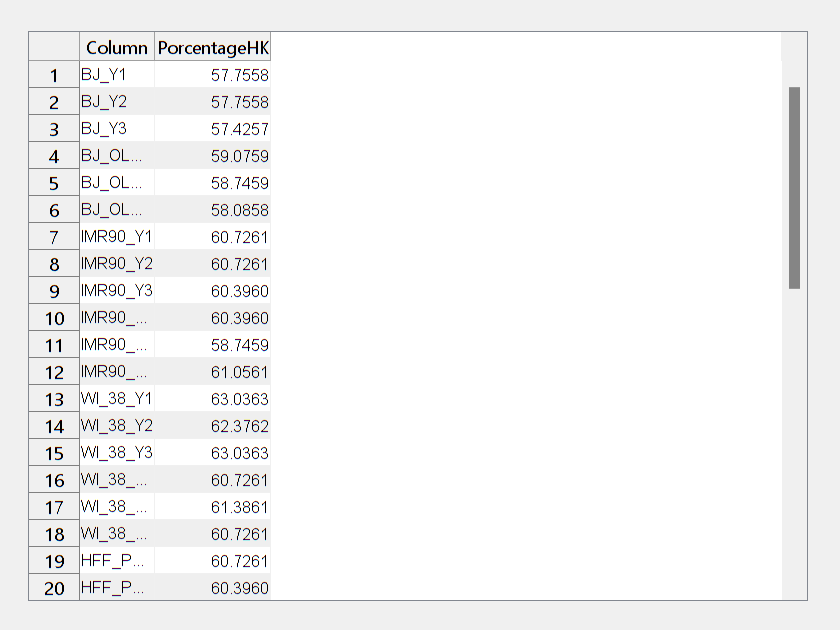

% Create a table with the results
f = figure('Name', 'Results', 'NumberTitle', 'off');
t = uitable(f, 'Data', table2cell(results), 'ColumnName', results_FPKM.Properties.VariableNames);
t.Position = [20 20 f.Position(3)-40 f.Position(4)-40];

# With TPM

clear all;
close all;

## Load the data again

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

% Transcriptomics data
data = readtable('Mod_data.xlsx');
% Housekeeping genes with the ensembl ids
h_k_g = readtable('housekeeping_ens.csv');
% Human1 metabolic model.
model = readCbModel('Human-GEM_Cobra_v1.01.mat');

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.


# Convert the data from FPKM to TPM

% Extract matrix from table
data_matrix = data{:, 2:end};

% Calculate the sum of each column
column_sums = sum(data_matrix, 1);

% Normalize each element by the sum of its column and then multiply by 10^6
normalized_matrix = (data_matrix ./ column_sums) * 1e6;

% Convert the normalized matrix back to a table
normalized_table = array2table(normalized_matrix, 'VariableNames', data.Properties.VariableNames(2:end));

% Replace the relevant columns in the original table
data(:, 2:end) = normalized_table;
data

data = 26269×49 table
      Ensembl_GeneID        BJ_Y1       BJ_Y2       BJ_Y3      BJ_OLD_1    BJ_OLD_2    BJ_OLD_3    IMR90_Y1    IMR90_Y2    IMR90_Y3    IMR90_O1    IMR90_O2    IMR90_O3    WI_38_Y1    WI_38_Y2    WI_38_Y3    WI_38_O1    WI_38_O2    WI_38_O3    HFF_PD16_1    HFF_PD16_2    HFF_PD16_3    HFF_PD74_1    HFF_PD74_2    HFF_PD74_3    MRC_5_PD32_1    MRC_5_PD32_2    MRC_5_PD32_3    MRC_5_PD72_1    MRC_5_PD72_2    MRC_5_PD72_3    HFF_PD26_1 

## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes;
% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :);

## For loop to calculate the percentage of all the samples

% Initialise a table to store the results
results = table;
% Get expression data column names
expression_col = data_met.Properties.VariableNames(2:end);
results_colname = []


results_colname =

     []



results_percentage_hk = []


results_percentage_hk =

     []



now create the for loop 

% Iterate over each column of expression data
for i = 1:length(expression_col)
    % Select the expression data column
    col_name = expression_col{i};
    expfibroblast = data_met(:,1); 
    expfibroblast(:,2) = data_met(:, col_name); 
    expfibroblast.Properties.VariableNames{1} = 'gene';
    expfibroblast.Properties.VariableNames{2} = 'FPKMvalue';

    % Perform the calculations
    expfibroblast.logFPKMvalue = log10(expfibroblast{:,2} + 1); 
    expfibroblast.value = expfibroblast.logFPKMvalue - min(expfibroblast.logFPKMvalue); 

    % Calculate the threshold, creating a slider form 70 to 100
    percentage =90;
    up_threshold_fib = prctile(expfibroblast.value, percentage);

    % Filtering the data
    idx = expfibroblast.value >= up_threshold_fib;
    filtered_data = expfibroblast(idx, :);

    % Select the ensembl id of the core genes
    genes_table = data_met.Ensembl_GeneID;
    
    %% housekeeping
    % See how many housekeeping genes in the list have metabolic functions. 
    index_names = ismember(genes_table, h_k_g.converted_alias);
    hkg_met = data_met(index_names, :);

    % Now just the ensmbl id
    hkg_met_ens = hkg_met(:, "Ensembl_GeneID");

    % Finding the housekeeping genes among the filtered genes
    ens_filt_dat = filtered_data.gene;
    matching_names_idx = ismember(ens_filt_dat, hkg_met_ens.Ensembl_GeneID);
    matching_names = filtered_data(matching_names_idx, 1);

    % Calculate the percentage of maintenance genes
    percentage_hk = (length(matching_names.gene) / length(ens_filt_dat)) * 100;

    % Save the results in the table
    results{i, 'Column'} = {col_name};
    results{i, 'PorcentageHK'} = percentage_hk;
   
end

results_TPM = results

results_TPM = 48×2 table
       Column       PorcentageHK
    ____________    ____________

    {'BJ_Y1'   }       57.756   
    {'BJ_Y2'   }       57.756   
    {'BJ_Y3'   }       57.426   
    {'BJ_OLD_1'}       59.076   
    {'BJ_OLD_2'}       58.746   
    {'BJ_OLD_3'}       58.086   
    {'IMR90_Y1'}       60.726   
    {'IMR90_Y2'}       60.726   
    {'IMR90_Y3'}       60.396   
    {'IMR90_O1'}       60.396   
    {'IMR90_O2'}       58.746   
    {'IMR90_O3'}       61.056   
    {'WI_38_Y1'}       63.036   
    {'WI_38_Y2'}       62.376   
    {'WI_38_Y3'}       63.036   
    {'WI_38_O1'}       60.726   


% Show results
disp(results_TPM);

         Column         PorcentageHK
    ________________    ____________

    {'BJ_Y1'       }       57.756   
    {'BJ_Y2'       }       57.756   
    {'BJ_Y3'       }       57.426   
    {'BJ_OLD_1'    }       59.076   
    {'BJ_OLD_2'    }       58.746   
    {'BJ_OLD_3'    }       58.086   
    {'IMR90_Y1'    }       60.726   
    {'IMR90_Y2'    }       60.726   
    {'IMR90_Y3'    }       60.396   
    {'IMR90_O1'    }       60.396   
    {'IMR90_O2'    }       58.746   
    {'IMR90_O3'    }       61.056   
    {'WI_38_Y1'    }       63.036   
    {'WI_38_Y2'    }       62.376   
    {'WI_38_Y3'    }       63.036   
    {'WI_38_O1'    }       60.726   
    {'WI_38_O2'    }       61.386   
    {'WI_38_O3'    }       60.726   
    {'HFF_PD16_1'  }       60.726   
    {'HFF_PD16_2'  }       60.396   
    {'HFF_PD16_3'  }       60.066   
    {'HFF_PD74_1'  }       59.406   
    {'HFF_PD74_2'  }       59.076   
    {'

Save the results table in a csv file

% Save the table in a CSV file
writetable(results_TPM, 'results_TPM.csv');

% Create a table with the results
f = figure('Name', 'Results', 'NumberTitle', 'off');
t = uitable(f, 'Data', table2cell(results), 'ColumnName', results_TPM.Properties.VariableNames);
t.Position = [20 20 f.Position(3)-40 f.Position(4)-40];